# Build Air Quality Model

Create a model to predict air quality from meteorological data (only). The model will be built and validated on large data (~1TB on an HDFS cluster) and will predict air quality for current conditions from a simple weather station.

Use local data to begin building the model, then scale to the larger set of data.

## Access raw data on Spark-enabled Hadoop cluster

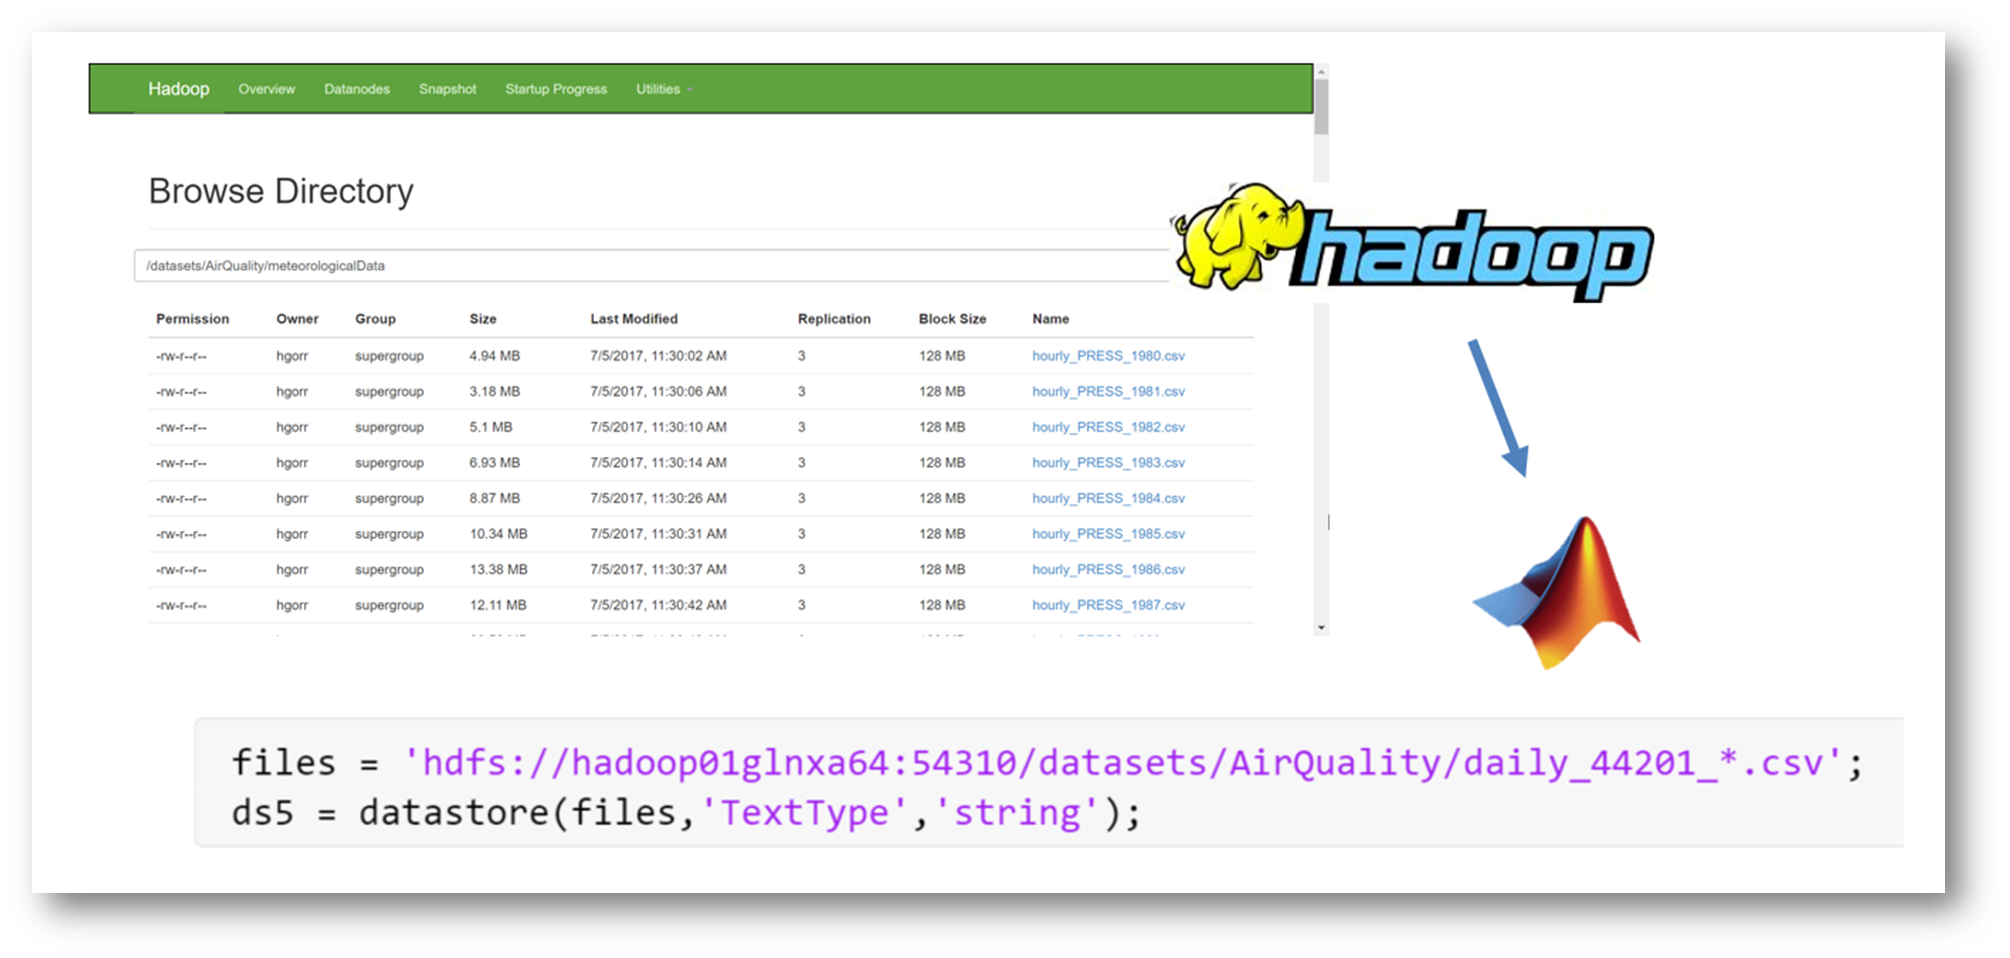

## Synchronize hourly and daily measurements

Historical data have mixed timestamps. The meteorological data are hourly measurements and the chemical measurements and AQI values are daily. Synchronize the data to daily averages and write preprocessed files using a Spark-enabled Hadoop cluster.

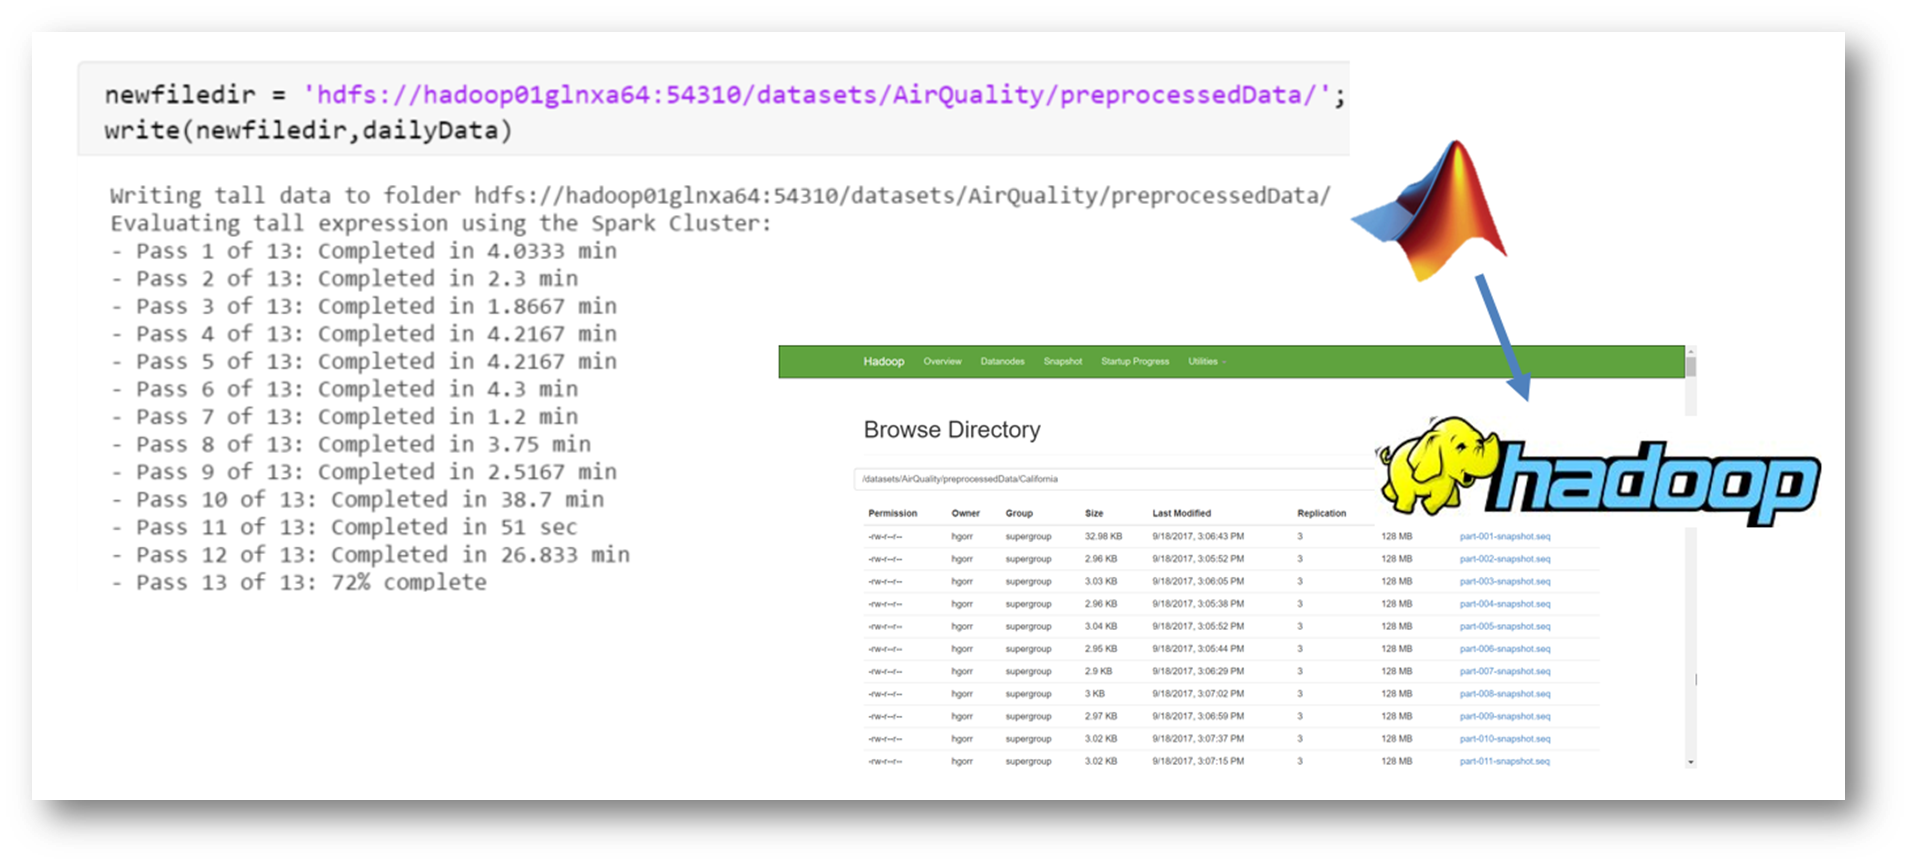

Now, analyze and build the model on the desktop using the preprocessed hourly data.

## Access daily data

The data have been preprocessed and saved locally as a .mat file. Use `fileDatastore` with a custom read function to work with all of these files.

filedir = "preprocessedData"+filesep+"*.parquet"; 
ds = datastore(filedir,"OutputType","timetable");
preview(ds)

ans = 8×12 timetable
         DateLocal             O3       AQI    StateName      CO       SO2       NO2        T        P     WindDir    WindSpd    DP     RH 
    ____________________    ________    ___    _________    ______    ______    ______    ______    ___    _______    _______    ___    ___

    01-Jan-1980 00:00:00     0.00775    13     "Alabama"    2.3208      3.75    22.917    47.625    NaN      NaN        NaN      NaN    NaN
    02-Jan-1980 00:00:00    0.006385    20     "Alabama"       6.8         0    34

Create a `tall` array to work with all data as one table (without reading all data into memory).

t = tall(ds);

## Explore the data

Visualize the data without bringing it into memory (use the command line for iterative display and control).

% scatter(t.DateLocal,t.AQI,".")

% binscatter(year(t.DateLocal),t.AQI)

Visualize the data on the Hadoop cluster.

% playVideo("BigData_plot.mp4")

## Preprocess data

Remove rows with all missing values. 

t = rmmissing(t,"MinNumMissing",width(t));

Represent the date as separate components and categorize the air quality to prepare the data for machine learning.

[t.yy,t.MM,t.dd] = ymd(t.DateLocal);
t.AQILabel = discretize(t.AQI,[0,51,101,151,201,301,500],"categorical",...
    ["Good","Moderate","Unhealthy for sensitive groups","Unhealthy",...
    "Very unhealthy","Hazardous"]);
t.StateName = categorical(t.StateName);

Calculate the average measurement value per year.

vars = ["AQI","O3","CO","SO2","NO2","T","P","WindDir","WindSpd","DP","RH"];
aqiOverTime = groupsummary(t,"DateLocal","year","mean",vars);

Get a sample of the data and gather the results into memory.

rng(123)
subset = datasample(t,10000,"Replace",false);

[subset,aqiOverTime] = gather(subset,aqiOverTime);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 5: Completed in 6.5 sec
- Pass 2 of 5: Completed in 5.5 sec
- Pass 3 of 5: Completed in 4.2 sec
- Pass 4 of 5: Completed in 5.1 sec
- Pass 5 of 5: Completed in 9.6 sec
Evaluation completed in 35 sec


## Explore further in-memory

Examine the average measurements over time.

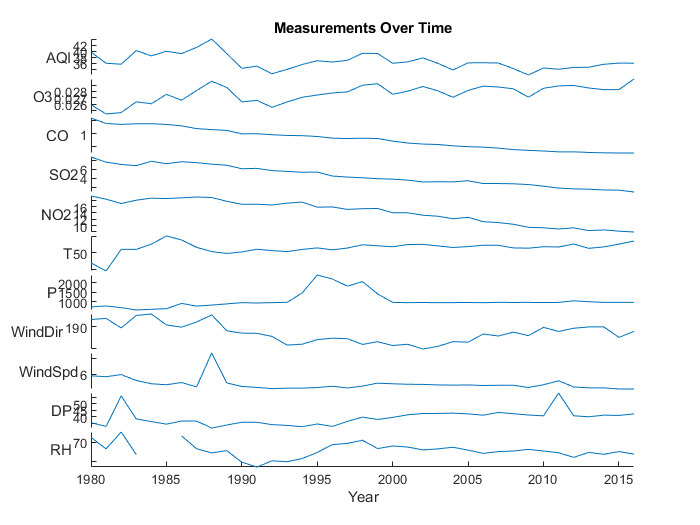

aqiOverTime.Properties.VariableNames = erase(aqiOverTime.Properties.VariableNames,"mean_");
aqiOverTime.Year = (1980:2016)';
figure
stackedplot(aqiOverTime,3:13,"XVariable","Year");
title("Measurements Over Time")

Examine the distribution of air quality measurements in the subset of data.

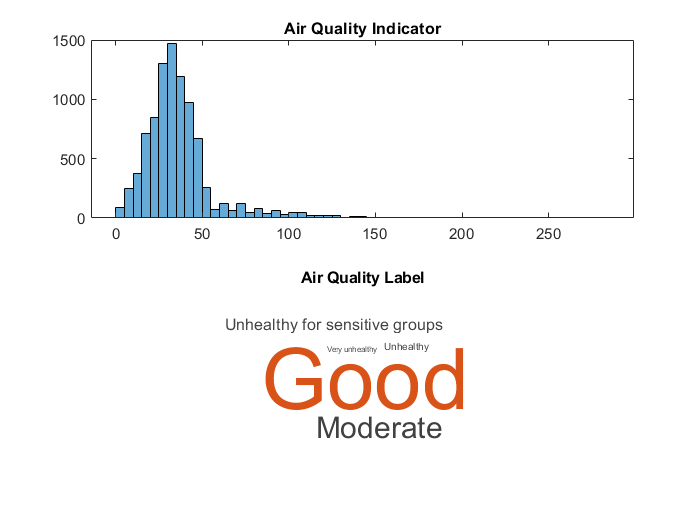

figure 
subplot(2,1,1)
histogram(subset.AQI);
title("Air Quality Indicator"); 
subplot(2,1,2)
wordcloud(subset.AQILabel); 
title("Air Quality Label")

The groups are unevenly distributed as most air quality is "Good" or "Moderate". This may need to be taken into account for the model. It is possible to sample using weights to get a more even distribution using `datasample`.

You can explore the data further by performing typical MATLAB analysis on the subset and then scale up to the full data set. For example, use the Signal Analyzer app to explore signal properties.

% open AirQualitySignals.mldatx

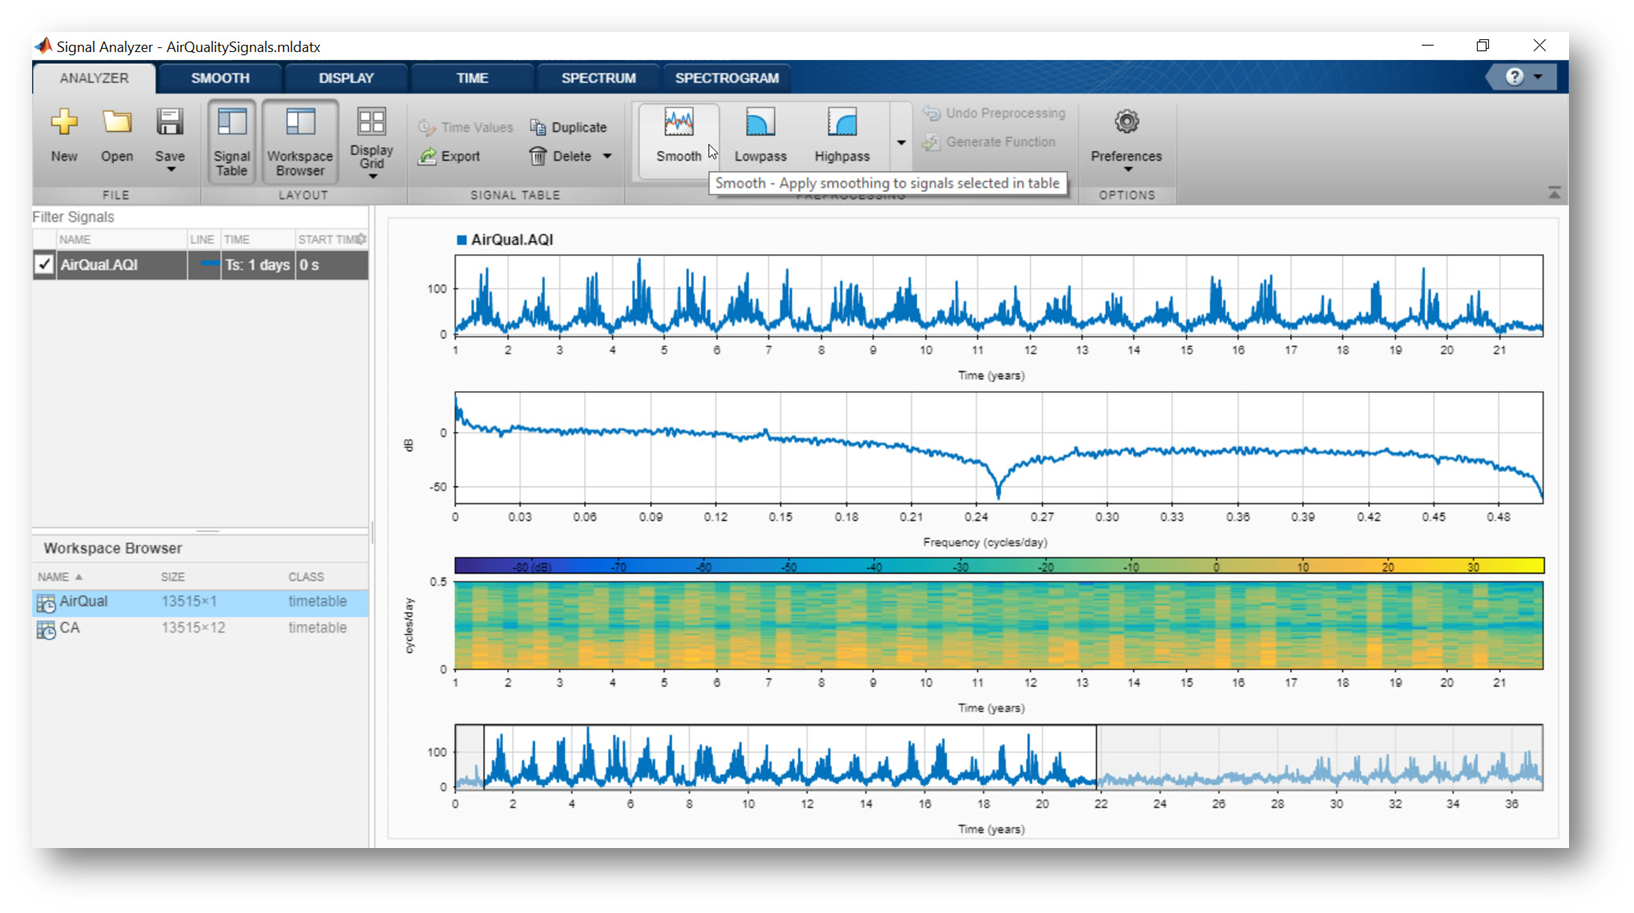

## Build machine learning model

Build a model using only the meteorological data to predict the air quality. Use the Classification Learner App to build the model (use the Regression Learner App to predict numeric AQI)

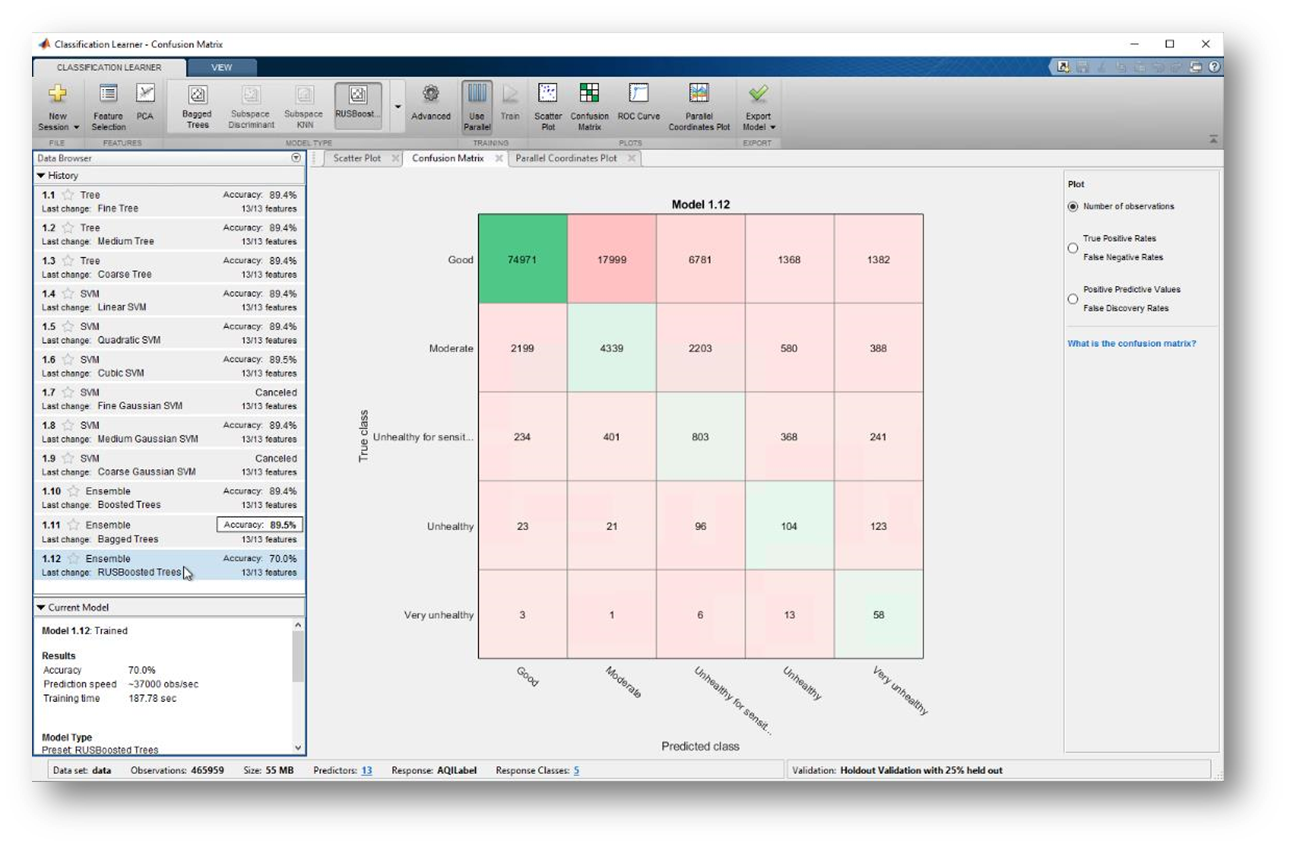

Prep the data for machine learning and split into training and test sets.

vars = ["StateName","T","P","WindDir","WindSpd","DP","RH","yy","MM","dd","AQILabel"];
data = timetable2table(subset(:,vars),"ConvertRowTimes",false);

cv = cvpartition(t.AQILabel,"holdout",0.2);
trainData = timetable2table(t(training(cv),:));
testData = timetable2table(t(test(cv),:));

Open the Classification Learner App and import `trainData`. Explore models and options and train.

% playVideo("MachineLearningAppVideo.mp4")

Export and save the trained model from the app. 

## Validate model

Load the saved model.

load airQualModel.mat

Predict air quality of the test data.

Predicted = predict(model,testData);

Gather the results and the original labels to memory. If the data are too big to fit in memory, calculate the loss and confusion matrix only: `err = loss(model,testData,testData.AQILabel)`

[Predicted,Actual] = gather(Predicted,testData.AQILabel);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 7.6 sec
Evaluation completed in 7.8 sec


Visualize results.

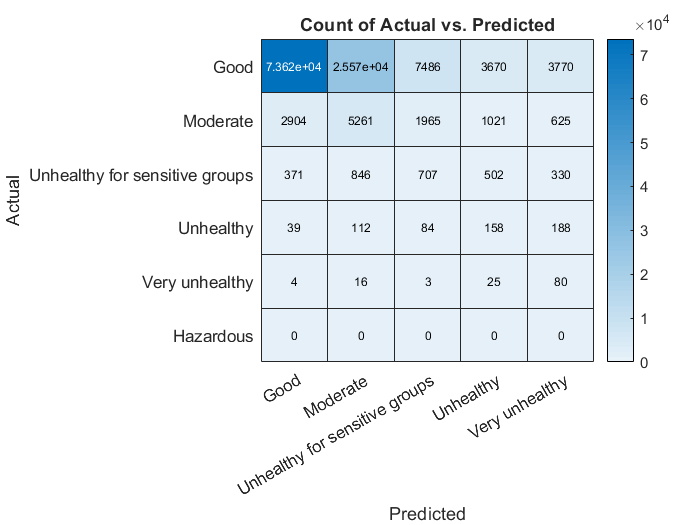

figure
heatmap(table(Predicted,Actual),"Predicted","Actual");

The model could be improved. The uneven distribution can be challenging for building models that generalize. There are a number of strategies such as sampling with weights, hyperparameter tuning, and more. The data could be better represented for machine learning as well by doing more sophisticated signal processing. 

See the documentation for more info:

[https://www.mathworks.com/help/stats/classification-model-building-and-assessment.html](https://www.mathworks.com/help/stats/classification-model-building-and-assessment.html)

## Use model in production

Save the model and the prediction steps in a function to be used in a Python web application.

% edit CallPythonFromMATLAB.mlx